clc
clear
close all

load F:\matlab\bin\App_Desgin\beijingData.mat

data = beijingdatas;
data = data';
PM25 = flip(data);
m = numel(PM25);

for j=1:m
    if PM25(j)<0 || PM25(j)> 1500
        PM25(j)=nan;
    end
end

PM25 = fillmissing(PM25,"linear");

PM = PM25;
PM = rmoutliers(PM,'quartiles');
PMM = [];

numHouser = 240;
for i = 1:numHouser
    PMM(:,i) = PM(i:end-numHouser+i);
end
PMM = PMM';

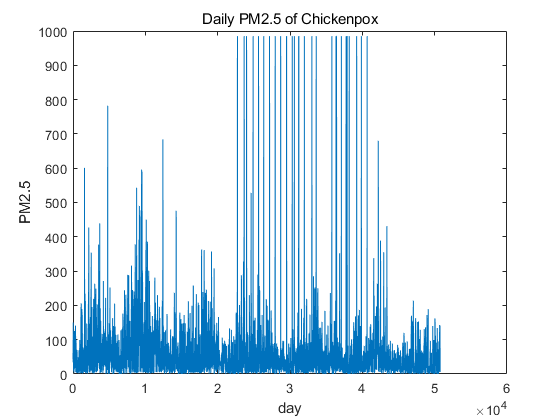

figure
m = numel(PM25);
y = 1:m;
plot(y,PM25)
xlabel("day")
ylabel("PM2.5")
title("Daily PM2.5 of Chickenpox")

x1 = 0;
x2 = 0;
x3 = 0;
x4 = 0;
x5 = 0;
x6 = 0;
m = numel(PM25);
for j=1:m
    if PM25(j)<=35
        PM25(j)=1; % 优
        x1 = x1+1;
    end
    if 35<PM25(j) && PM25(j)<=75 % 良
        PM25(j)=2;
        x2 = x2+1;
    end
    if 75<PM25(j) && PM25(j)<=115 % 轻度污染
        PM25(j)=3;
        x3 = x3+1;
    end
    if 115<PM25(j) && PM25(j)<=150 % 中度污染
        PM25(j)=4;
        x4 = x4+1;
    end
    if 150<PM25(j) && PM25(j)<=250 % 重度污染
        PM25(j)=5;
        x5 = x5+1;
    end
    if 250<PM25(j) && PM25(j)<=350 % 严重污染
        PM25(j)=6;
        x6 = x6+1;
    end
    if 350<PM25(j) % 严重污染
        PM25(j)=6;
        x6 = x6+1;
    end
end



x = [x1/m x2/m x3/m x4/m x5/m x6/m]

x =    0.520959735245450   0.276554251044047   0.103774328264124   0.041151209518556   0.043849972421401   0.013710503506422


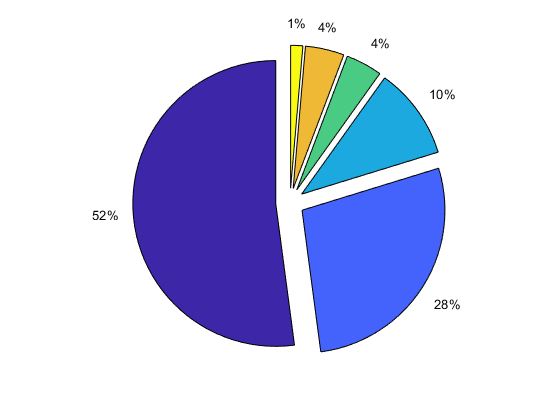

labels = {'优56%','良28%','轻度污染10%','中度污染4%','重度污染4%','严重污染1%'};
pie(x,'%.3f%%');

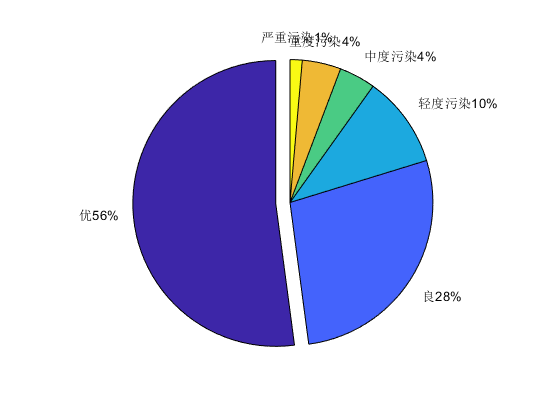

explode =  [1 0 0 0 0 0];
pie(x,explode,labels)

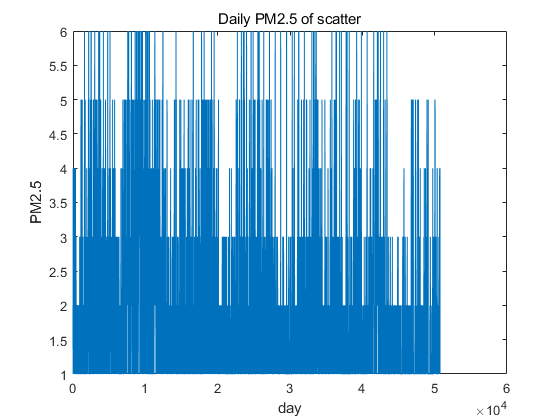


y = 1:m;
figure
plot(y,PM25)
xlabel("day")
ylabel("PM2.5")
title("Daily PM2.5 of scatter")

% LABEL = PM25;
% index = 1;
% DATA = zeros(index,m-index+1);
% for i=1:index
%     DATA(i,:) = PM(i:end-index+i);  
% end
% DATALabel = PM25(index+1:end);
DATA = PMM;

[c,l] = size(DATA);
numTimeStepsTrain = floor(0.90*l);

for i = 1:numHouser
    dataTrain(i,:) = DATA(i,1:numTimeStepsTrain+1);
end


for i = 1:numHouser
    dataTest(i,:) = DATA(i,numTimeStepsTrain+1:end);
end


[~,Xrule] = mapminmax(dataTrain);
dataTrainStandardized = mapminmax('apply',dataTrain,Xrule);
XTrain = dataTrainStandardized(:,1:end-numHouser+1);

YTrain = dataTrain(1,numHouser:end);

[~,Yrule] = mapminmax(YTrain);
YTrain = mapminmax('apply',YTrain,Yrule);

numFeatures = numHouser;
numResponses = 1;
numHiddenUnits1 = 200;
% numHiddenUnits2 = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    fullyConnectedLayer(200)
    lstmLayer(numHiddenUnits1)
%     lstmLayer(numHiddenUnits2)
    dropoutLayer(0.2)
    fullyConnectedLayer(200)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',100, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.0005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',75, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');


% net = trainNetwork(XTrain,YTrain,layers,options);
load ..\bin\App_Desgin\BeijingNet2.mat

load ..\bin\App_Desgin\BeijingNet2.mat;

dataTestStandardized = mapminmax('apply',dataTest,Xrule);
XTest = dataTestStandardized(:,1:end-numHouser);

Ytest = dataTest(1,numHouser:end-1);

Ytest = mapminmax('apply',Ytest,Yrule);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,XTrain(:,end));

mid = XTrain(:,end);
for i = 1:numHouser-1
    mid(i) = mid(i+1);
end


mid(end) = YPred;

YPred = mid;

[c,l] = size(XTest);

for i = 1:l
    [net,rs(i)] = predictAndUpdateState(net,YPred(:,1),'ExecutionEnvironment','cpu');
    for j = 1:numHouser-1
        YPred(j)=YPred(j+1);
    end
    YPred(end) = rs(i);
end

endrs = mapminmax('reverse',rs,Yrule);

Ytest = mapminmax('reverse',Ytest,Yrule);

rmse = sqrt(mean((endrs-Ytest).^2))

rmse = single
  37.4313164


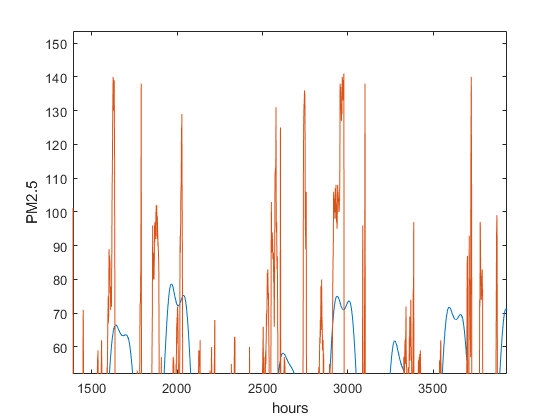


index = 0:numel(endrs)-1;

plot(index,endrs);hold on;
plot(index,Ytest);hold off

xlabel('hours')
ylabel('PM2.5')



m = numel(endrs);
for j=1:m
    if endrs(j)<=35
        endrs(j)=1; % 优
    end
    if 35<endrs(j) && endrs(j)<=75 % 良
        endrs(j)=2;
    end
    if 75<endrs(j) && endrs(j)<=115 % 轻度污染
        endrs(j)=3;
    end
    if 115<endrs(j) && endrs(j)<=150 % 中度污染
        endrs(j)=4;
    end
    if 150<endrs(j) && endrs(j)<=250 % 重度污染
        endrs(j)=5;
    end
    if 250<endrs(j) && endrs(j)<=350 % 严重污染
        endrs(j)=6;
    end
    if 350<endrs(j) % 严重污染
        endrs(j)=6;
    end
end

m = numel(Ytest);
for j=1:m
    if Ytest(j)<=35
        Ytest(j)=1; % 优
    end
    if 35<Ytest(j) && Ytest(j)<=75 % 良
        Ytest(j)=2;
    end
    if 75<Ytest(j) && Ytest(j)<=115 % 轻度污染
        Ytest(j)=3;
    end
    if 115<Ytest(j) && Ytest(j)<=150 % 中度污染
        Ytest(j)=4;
    end
    if 150<Ytest(j) && Ytest(j)<=250 % 重度污染
        Ytest(j)=5;
    end
    if 250<Ytest(j) && Ytest(j)<=350 % 严重污染
        Ytest(j)=6;
    end
    if 350<Ytest(j) % 严重污染
        Ytest(j)=6;
    end
end
Pre72 = endrs(1:73);
Test72 = Ytest(1:73);
PreLabelloss = sqrt(mean((Pre72-Test72).^2))
figure
plot(Pre72)
hold on;

PreLabelloss = single
   0.8862793


plot(Test72)

预测

PreData = DATA(:,end-numFeatures:end)

PreData = 	1.0e+02 *

   0.520000000000000   0.510000000000000   0.280000000000000   0.070000000000000   0.040000000000000   0.030000000000000   0.020000000000000   0.070000000000000   0.070000000000000   0.080000000000000   0.060000000000000   0.050000000000000   0.070000000000000   0.060000000000000   0.030000000000000   0.030000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.020000000000000   0.010000000000000   0.040000000000000   0.040000000000000   0.020000000000000   0.050000000000000   0.040000000000000   0.070000000000000   0.080000000000000   0.070000000000000   0.090000000000000   0.060000000000000   0.060000000000000   0.120000000000000   0.080000000000000   0.100000000000000   0.070000000000000   0.080000000000000   0.080000000000000   0.090000000000000   0.140000000000000   0.110000000000000   0.070000000000000   0.070000000000000   0.070000000000000   0.060000000000000   0.120000000000000   0.090000000000000   0.120000000000000   0.2200000000000

dataPreStandardized = mapminmax('apply',PreData,Xrule);
PreData = dataPreStandardized;

net = predictAndUpdateState(net,XTest);

for i = 1:72
    [net,prs(i)] = predictAndUpdateState(net,PreData(:,i),'ExecutionEnvironment','cpu');
end

pendrs = mapminmax('reverse',prs,Yrule);


m = numel(pendrs);
for j=1:m
    if pendrs(j)<=35
        pendrs(j)=1; % 优
    end
    if 35<pendrs(j) && pendrs(j)<=75 % 良
        pendrs(j)=2;
    end
    if 75<pendrs(j) && pendrs(j)<=115 % 轻度污染
        pendrs(j)=3;
    end
    if 115<pendrs(j) && pendrs(j)<=150 % 中度污染
        pendrs(j)=4;
    end
    if 150<pendrs(j) && pendrs(j)<=250 % 重度污染
        pendrs(j)=5;
    end
    if 250<pendrs(j) && pendrs(j)<=350 % 严重污染
        pendrs(j)=6;
    end
    if 350<pendrs(j) % 严重污染
        pendrs(j)=6;
    end
end


save ..\bin\App_Desgin\BeijingNet2.mat net

save ..\bin\App_Desgin\PendRs.mat pendrs

save ..\bin\App_Desgin\D1215.mat D1215

m = numel(D1215);
for j=1:m
    if D1215(j)<=35
        D1215(j)=1; % 优
    end
    if 35<D1215(j) && D1215(j)<=75 % 良
        D1215(j)=2;
    end
    if 75<D1215(j) && D1215(j)<=115 % 轻度污染
        D1215(j)=3;
    end
    if 115<D1215(j) && D1215(j)<=150 % 中度污染
        D1215(j)=4;
    end
    if 150<D1215(j) && D1215(j)<=250 % 重度污染
        D1215(j)=5;
    end
    if 250<D1215(j) && D1215(j)<=350 % 严重污染
        D1215(j)=6;
    end
    if 350<D1215(j) % 严重污染
        D1215(j)=6;
    end
end